# Cinematica diretta completa

## Manipolatore sferico di primo tipo

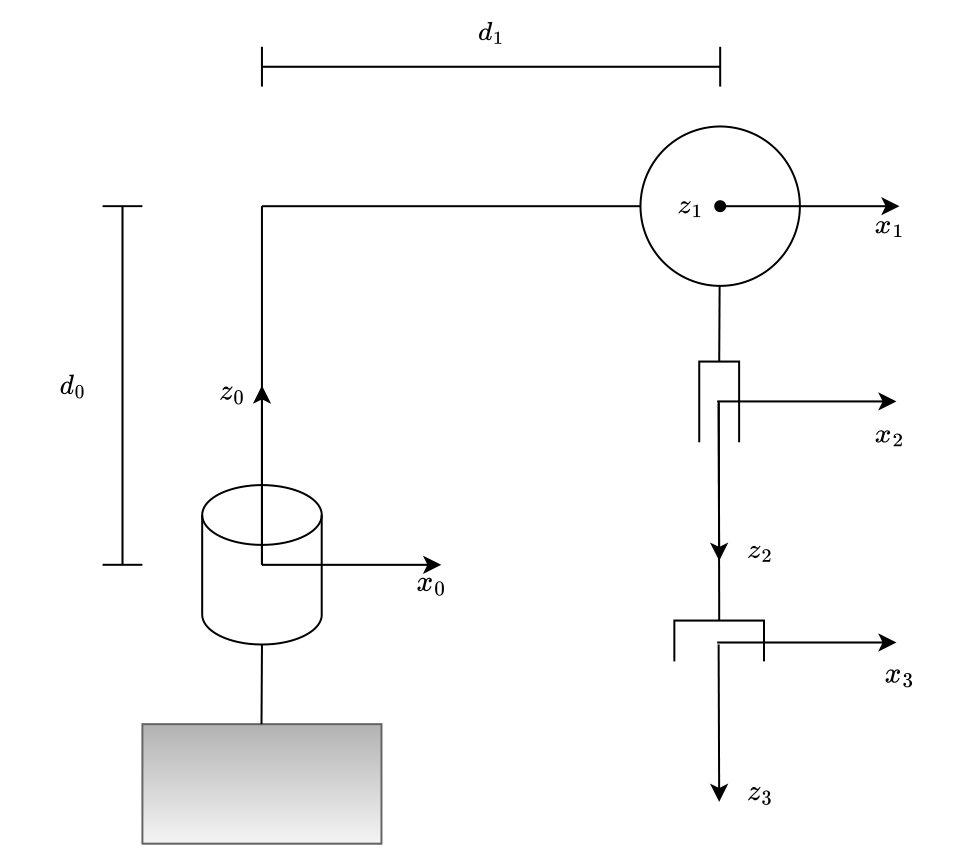

syms q1 q2 q3 d0 d1 real
DHsferico1tipo = [d1, pi/2, d0, q1;
                0, pi/2, 0, q2;
                0, 0, q3, 0]

$$DHsferico1tipo = \left(\begin{array}{cccc} d_{1} & \frac{\pi }{2} & d_{0} & q_{1}\\ 0 & \frac{\pi }{2} & 0 & q_{2}\\ 0 & 0 & q_{3} & 0 \end{array}\right)$$

TsfericoList = cinDirDH(DHsferico1tipo);
T01 = TsfericoList{1}

$$T01 = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & 0 & \sin\left(q_{1}\right) & d_{1}\,\cos\left(q_{1}\right)\\ \sin\left(q_{1}\right) & 0 & -\cos\left(q_{1}\right) & d_{1}\,\sin\left(q_{1}\right)\\ 0 & 1 & 0 & d_{0}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T12 = TsfericoList{2}

$$T12 = \left(\begin{array}{cccc} \cos\left(q_{2}\right) & 0 & \sin\left(q_{2}\right) & 0\\ \sin\left(q_{2}\right) & 0 & -\cos\left(q_{2}\right) & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T23 = TsfericoList{3}

$$T23 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & q_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T03 = TsfericoList{4}

$$T03 = \begin{array}{l} \left(\begin{array}{cccc} \cos\left(q_{1}\right)\,\cos\left(q_{2}\right) & \sin\left(q_{1}\right) & \cos\left(q_{1}\right)\,\sin\left(q_{2}\right) & \cos\left(q_{1}\right)\,\sigma_{1}\\ \cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & -\cos\left(q_{1}\right) & \sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & \sin\left(q_{1}\right)\,\sigma_{1}\\ \sin\left(q_{2}\right) & 0 & -\cos\left(q_{2}\right) & d_{0}-q_{3}\,\cos\left(q_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=d_{1}+q_{3}\,\sin\left(q_{2}\right) \end{array}$$

## Manipolatore SCARA

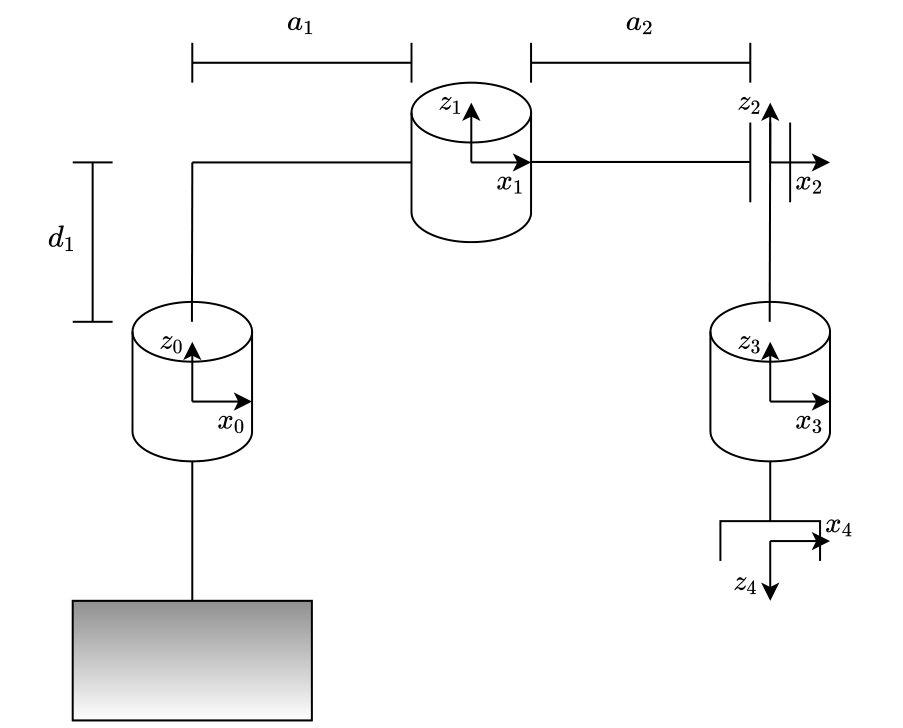

syms q1 q2 q3 q4 d1 d4 a1 a2 real
DHscara = [a1, 0, d1, q1;
           a2, 0, 0, q2;
           0, 0, q3, 0;
           0, pi, d4, q4]

$$DHscara = \left(\begin{array}{cccc} a_{1} & 0 & d_{1} & q_{1}\\ a_{2} & 0 & 0 & q_{2}\\ 0 & 0 & q_{3} & 0\\ 0 & \pi & d_{4} & q_{4} \end{array}\right)$$

TscaraList = cinDirDH(DHscara);
T01 = TscaraList{1}

$$T01 = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0 & a_{1}\,\cos\left(q_{1}\right)\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0 & a_{1}\,\sin\left(q_{1}\right)\\ 0 & 0 & 1 & d_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T12 = TscaraList{2}

$$T12 = \left(\begin{array}{cccc} \cos\left(q_{2}\right) & -\sin\left(q_{2}\right) & 0 & a_{2}\,\cos\left(q_{2}\right)\\ \sin\left(q_{2}\right) & \cos\left(q_{2}\right) & 0 & a_{2}\,\sin\left(q_{2}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T23 = TscaraList{3}

$$T23 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & q_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T34 = TscaraList{4}

$$T34 = \left(\begin{array}{cccc} \cos\left(q_{4}\right) & \sin\left(q_{4}\right) & 0 & 0\\ \sin\left(q_{4}\right) & -\cos\left(q_{4}\right) & 0 & 0\\ 0 & 0 & -1 & d_{4}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T04 = TscaraList{5}

$$T04 = \left(\begin{array}{cccc} \cos\left(q_{1}+q_{2}+q_{4}\right) & \sin\left(q_{1}+q_{2}+q_{4}\right) & 0 & a_{2}\,\cos\left(q_{1}+q_{2}\right)+a_{1}\,\cos\left(q_{1}\right)\\ \sin\left(q_{1}+q_{2}+q_{4}\right) & -\cos\left(q_{1}+q_{2}+q_{4}\right) & 0 & a_{2}\,\sin\left(q_{1}+q_{2}\right)+a_{1}\,\sin\left(q_{1}\right)\\ 0 & 0 & -1 & d_{1}+d_{4}+q_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

## Manipolatore antropomorfo

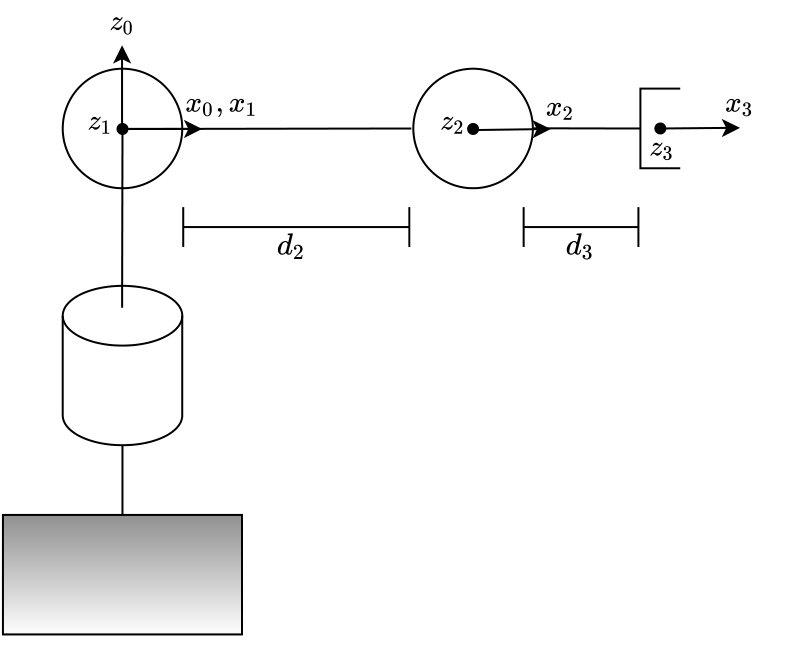

syms q1 q2 q3 d2 d3 real
DHant = [0, pi/2, 0, q1;
           d2, 0, 0, q2;
           d3, 0, 0, q3]

$$DHant = \left(\begin{array}{cccc} 0 & \frac{\pi }{2} & 0 & q_{1}\\ d_{2} & 0 & 0 & q_{2}\\ d_{3} & 0 & 0 & q_{3} \end{array}\right)$$

TantList = cinDirDH(DHant);
T01 = TantList{1}

$$T01 = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & 0 & \sin\left(q_{1}\right) & 0\\ \sin\left(q_{1}\right) & 0 & -\cos\left(q_{1}\right) & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T12 = TantList{2}

$$T12 = \left(\begin{array}{cccc} \cos\left(q_{2}\right) & -\sin\left(q_{2}\right) & 0 & d_{2}\,\cos\left(q_{2}\right)\\ \sin\left(q_{2}\right) & \cos\left(q_{2}\right) & 0 & d_{2}\,\sin\left(q_{2}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T23 = TantList{3}

$$T23 = \left(\begin{array}{cccc} \cos\left(q_{3}\right) & -\sin\left(q_{3}\right) & 0 & d_{3}\,\cos\left(q_{3}\right)\\ \sin\left(q_{3}\right) & \cos\left(q_{3}\right) & 0 & d_{3}\,\sin\left(q_{3}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T03 = TantList{4}

$$T03 = \begin{array}{l} \left(\begin{array}{cccc} \cos\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right) & -\sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right) & \sin\left(q_{1}\right) & \cos\left(q_{1}\right)\,\sigma_{1}\\ \cos\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right) & -\sin\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right) & -\cos\left(q_{1}\right) & \sin\left(q_{1}\right)\,\sigma_{1}\\ \sin\left(q_{2}+q_{3}\right) & \cos\left(q_{2}+q_{3}\right) & 0 & d_{3}\,\sin\left(q_{2}+q_{3}\right)+d_{2}\,\sin\left(q_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=d_{3}\,\cos\left(q_{2}+q_{3}\right)+d_{2}\,\cos\left(q_{2}\right) \end{array}$$

## Manipolatore di Stanford (solo struttura portante = manipolatore sferico di II tipo)

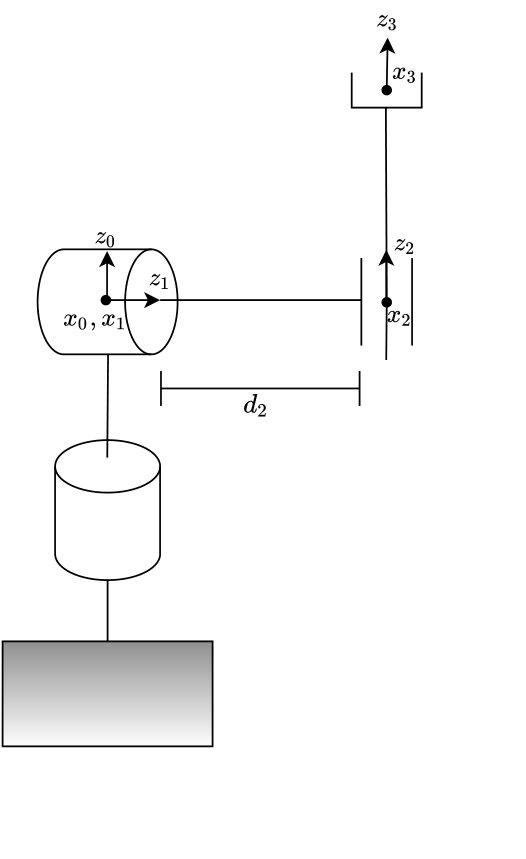

syms q1 q2 q3 d2 real
DHsferico = [0, -pi/2, 0, q1;
            0, pi/2, d2, q2;
            0, 0, q3, 0]

$$DHsferico = \left(\begin{array}{cccc} 0 & -\frac{\pi }{2} & 0 & q_{1}\\ 0 & \frac{\pi }{2} & d_{2} & q_{2}\\ 0 & 0 & q_{3} & 0 \end{array}\right)$$

TsfericoList = cinDirDH(DHsferico);
T01 = TsfericoList{1}

$$T01 = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & 0 & -\sin\left(q_{1}\right) & 0\\ \sin\left(q_{1}\right) & 0 & \cos\left(q_{1}\right) & 0\\ 0 & -1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T12 = TsfericoList{2}

$$T12 = \left(\begin{array}{cccc} \cos\left(q_{2}\right) & 0 & \sin\left(q_{2}\right) & 0\\ \sin\left(q_{2}\right) & 0 & -\cos\left(q_{2}\right) & 0\\ 0 & 1 & 0 & d_{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T23 = TsfericoList{3}

$$T23 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & q_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T03 = TsfericoList{4}

$$T03 = \left(\begin{array}{cccc} \cos\left(q_{1}\right)\,\cos\left(q_{2}\right) & -\sin\left(q_{1}\right) & \cos\left(q_{1}\right)\,\sin\left(q_{2}\right) & q_{3}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)-d_{2}\,\sin\left(q_{1}\right)\\ \cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & \cos\left(q_{1}\right) & \sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & d_{2}\,\cos\left(q_{1}\right)+q_{3}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ -\sin\left(q_{2}\right) & 0 & \cos\left(q_{2}\right) & q_{3}\,\cos\left(q_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

## Polso sferico    

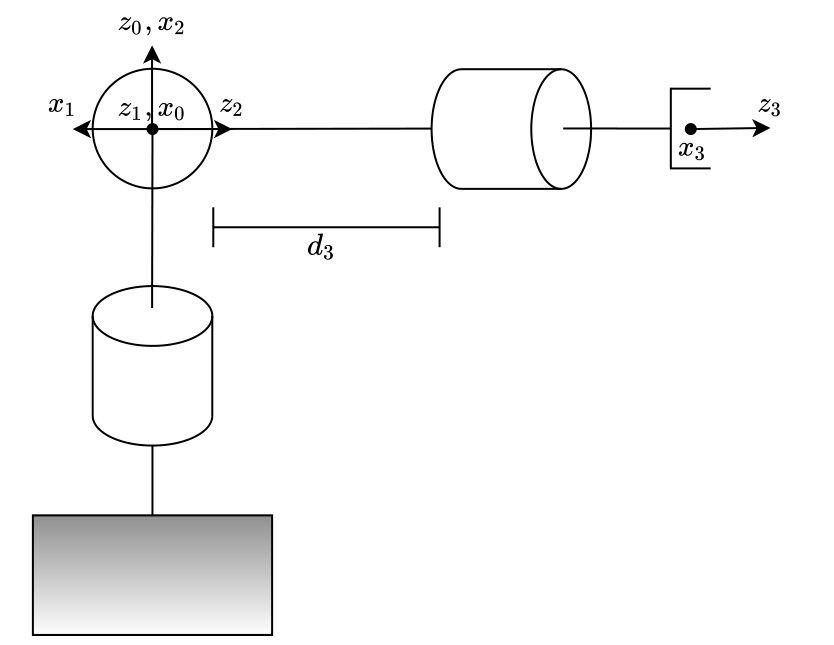

syms q1 q2 q3 d3 real
DHpolso = [0, -pi/2, 0, q1;
           0, pi/2, 0, q2;
           0, 0, d3, q3]

$$DHpolso = \left(\begin{array}{cccc} 0 & -\frac{\pi }{2} & 0 & q_{1}\\ 0 & \frac{\pi }{2} & 0 & q_{2}\\ 0 & 0 & d_{3} & q_{3} \end{array}\right)$$

TpolsoList = cinDirDH(DHpolso);
T01 = TpolsoList{1}

$$T01 = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & 0 & -\sin\left(q_{1}\right) & 0\\ \sin\left(q_{1}\right) & 0 & \cos\left(q_{1}\right) & 0\\ 0 & -1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T12 = TpolsoList{2}

$$T12 = \left(\begin{array}{cccc} \cos\left(q_{2}\right) & 0 & \sin\left(q_{2}\right) & 0\\ \sin\left(q_{2}\right) & 0 & -\cos\left(q_{2}\right) & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T23 = TpolsoList{3}

$$T23 = \left(\begin{array}{cccc} \cos\left(q_{3}\right) & -\sin\left(q_{3}\right) & 0 & 0\\ \sin\left(q_{3}\right) & \cos\left(q_{3}\right) & 0 & 0\\ 0 & 0 & 1 & d_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T03 = TpolsoList{4}

$$T03 = \left(\begin{array}{cccc} \cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-\sin\left(q_{1}\right)\,\sin\left(q_{3}\right) & -\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)-\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\sin\left(q_{3}\right) & \cos\left(q_{1}\right)\,\sin\left(q_{2}\right) & d_{3}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ \cos\left(q_{1}\right)\,\sin\left(q_{3}\right)+\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right) & \cos\left(q_{1}\right)\,\cos\left(q_{3}\right)-\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{3}\right) & \sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & d_{3}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ -\cos\left(q_{3}\right)\,\sin\left(q_{2}\right) & \sin\left(q_{2}\right)\,\sin\left(q_{3}\right) & \cos\left(q_{2}\right) & d_{3}\,\cos\left(q_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

## Manipolatore di Stanford

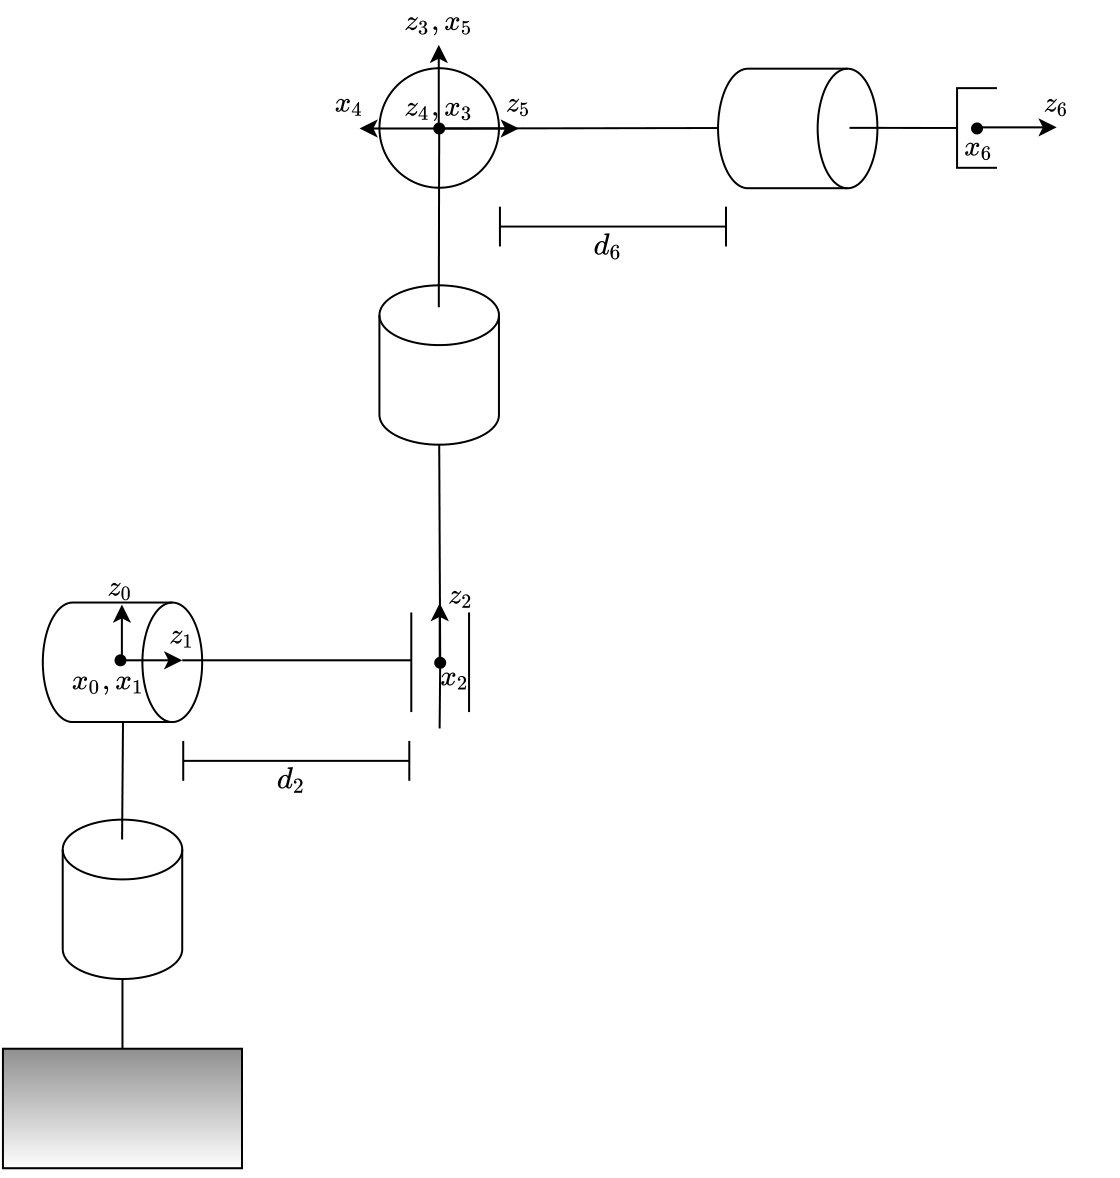

syms q1 q2 q3 q4 q5 q6 d2 d6 real
DHstanford = [0, -pi/2, 0, q1;
             0, pi/2, d2, q2;
             0, 0, q3, 0;
             0, -pi/2, 0, q4;
             0, pi/2, 0, q5;
             0, 0, d6, q6]

$$DHstanford = \left(\begin{array}{cccc} 0 & -\frac{\pi }{2} & 0 & q_{1}\\ 0 & \frac{\pi }{2} & d_{2} & q_{2}\\ 0 & 0 & q_{3} & 0\\ 0 & -\frac{\pi }{2} & 0 & q_{4}\\ 0 & \frac{\pi }{2} & 0 & q_{5}\\ 0 & 0 & d_{6} & q_{6} \end{array}\right)$$

TstanfordList = cinDirDH(DHstanford);
T01 = TstanfordList{1}

$$T01 = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & 0 & -\sin\left(q_{1}\right) & 0\\ \sin\left(q_{1}\right) & 0 & \cos\left(q_{1}\right) & 0\\ 0 & -1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T12 = TstanfordList{2}

$$T12 = \left(\begin{array}{cccc} \cos\left(q_{2}\right) & 0 & \sin\left(q_{2}\right) & 0\\ \sin\left(q_{2}\right) & 0 & -\cos\left(q_{2}\right) & 0\\ 0 & 1 & 0 & d_{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T23 = TstanfordList{3}

$$T23 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & q_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T34 = TstanfordList{4}

$$T34 = \left(\begin{array}{cccc} \cos\left(q_{4}\right) & 0 & -\sin\left(q_{4}\right) & 0\\ \sin\left(q_{4}\right) & 0 & \cos\left(q_{4}\right) & 0\\ 0 & -1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T45 = TstanfordList{5}

$$T45 = \left(\begin{array}{cccc} \cos\left(q_{5}\right) & 0 & \sin\left(q_{5}\right) & 0\\ \sin\left(q_{5}\right) & 0 & -\cos\left(q_{5}\right) & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T56 = TstanfordList{6}

$$T56 = \left(\begin{array}{cccc} \cos\left(q_{6}\right) & -\sin\left(q_{6}\right) & 0 & 0\\ \sin\left(q_{6}\right) & \cos\left(q_{6}\right) & 0 & 0\\ 0 & 0 & 1 & d_{6}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T06 = TstanfordList{7}

Lo stesso risultato poteva essere ottenuto concatenando la cinematica del manipolatore sferico con la cinematica del polso sferico ${^0 \textbf{T}_6} = \underbrace{{^0 \textbf{T}_3}}_{\text{man. sferico }}\underbrace{{^0 \textbf{T}_{3}}}_{\text{ polso sferico}}$.

DHsferico = [0, -pi/2, 0, q1;
             0, pi/2, d2, q2;
             0, 0, q3, 0];
DHpolso = [0, -pi/2, 0, q4;
           0, pi/2, 0, q5;
           0, 0, d6, q6];

TsfericoList = cinDirDH(DHsferico);
TpolsoList = cinDirDH(DHpolso);

T03_manSferico = TsfericoList{4};
T03_polso = TpolsoList{4};
T06_2 = simplify(T03_manSferico*T03_polso);
isequal(expand(T06), expand(T06_2))

ans = logical
   1
